# EXERCISE #2 : Simulate a Bluetooth LE wireless sensor network under WLAN interference. 

Bluetooth LE Piconet 

**In this exercise, you will:**

- Model a Bluetooth sensor network.

- Add WLAN interference and visualize the impact.

- Measure key performance indicators (KPIs) such as throughput.

- Quantify the impact of interference.

- Perform cleanup by closing previously opened windows and figures. 

- Initialize the random number generator for reproducibility

- Set the simulation time

- Initialize the network simulator

- Launch the wireless network viewer to visualize the network during simulation

clear all;
all_figs = findall(0, 'type', 'figure');close(all_figs);
rng(1,"twister");
simulationTime = 0.5;
networkSimulator = wirelessNetworkSimulator.init;
viewerObj = wirelessNetworkViewer();

Create a Bluetooth Low Energy (LE) central node

- A central node 

- Manages connections, 

- Discovers nearby peripherals

- Initiates communication

- Coordinates data exchange

- Configure parameters such as role, name, position, and transmit power

- Add the node to the Wireless Network Viewer

- Refer to documentation for more details on creating a Bluetooth LE node (Type *doc bluetoothLENode* in command window)

centralNode = bluetoothLENode("central", ...
    "Name","CN", ...
    Position=[0 0 0], ...
    TransmitterPower=-20);
addNodes(viewerObj,centralNode,Type="Source",Name=centralNode.Name);

Create a Bluetooth Low Energy (LE) peripheral node

- The Bluetooth SIG defines roles for Bluetooth LE devices, such as 

- Central, 

- Peripheral, 

- Broadcaster and more 

- Create three peripheral nodes

- Add the peripheral nodes to the Wireless Network Viewer

peripheralNode = bluetoothLENode("peripheral", ...
    Position=[-5 4 0; 0 5 0;5 4 0], ...
    Name=["PN-1", "PN-2","PN-3"], ...
    TransmitterPower=-20);
addNodes(viewerObj,peripheralNode,Type="Sink");

Each row in the following diagram corresponds to connection between the central and a peripheral device  

- The blue blocks show when devices communicate (connection events)

- The gray parts show when data is actually exchanged (active period)

- The green bars are packets sent between central and peripheral

- The white gaps are small delays between packets 

- The connection offset sets different start times so devices don’t communicate at the same time

These timing parameters are important because they affect network performance. You can tune them to achieve the desired performance.

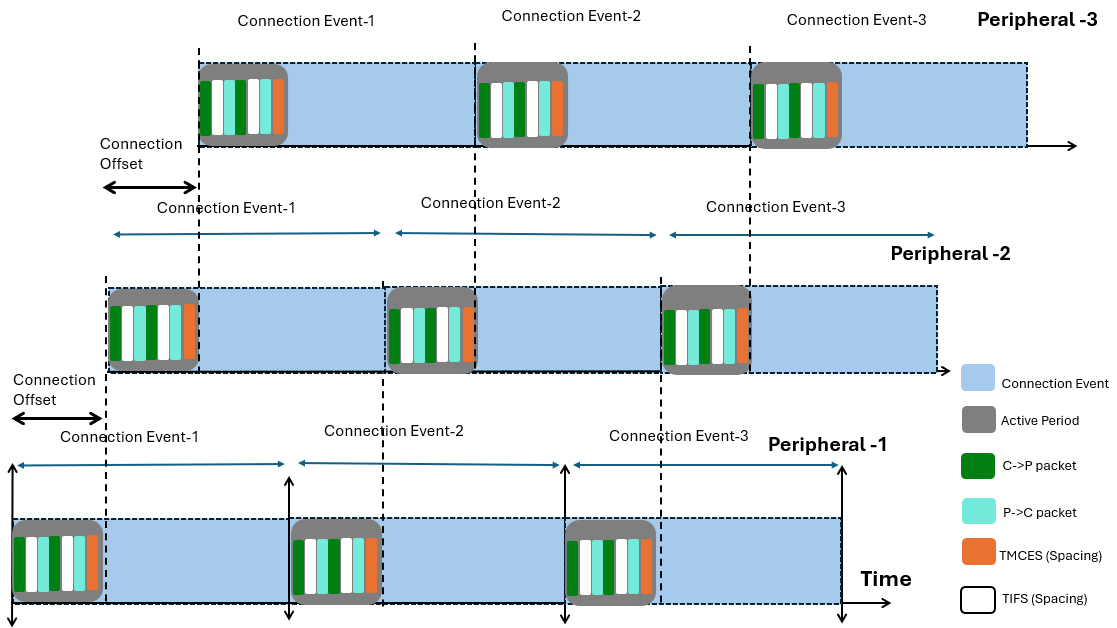

- Connection interval is 75 ms

- active period is 5 ms

connectionInterval = 0.075; 
activePeriod       = 0.005; 

- Offset for starting connection event is different for the three links  

- PHY mode, specified as "LE1M", "LE2M", "LE125K", or "LE500K"

- Before connection: “Who am I?” → MAC address,  After connection: “Which link?” → Access Address

- Algorithm, specified as 1 or 2 representing "Algorithm #1" or "Algorithm #2

connectionOffset   = [0,0.025,0.050];
phyMode            = ["LE1M","LE1M","LE1M"];
accessAddress      = ["5DA44270","5DA44271","5DA44272"];
algorithm          = [1,1,2]; 

# Task 2/2: Define the link configuration for the 1st link in the network  

Use doc bluetoothLEConnectionConfig to see details on configuring the Bluetooth LE connection

Write configuration in a variable named "cfgConnection"

 Note : Call bluetoothLEConnectionConfig and use the following values arguments to start with

- ConnectionInterval=connectionInterval

- ActivePeriod=activePeriod

- ConnectionOffset=connectionOffset(1)

- PHYMode = phyMode(1)

- AccessAddress=accessAddress(1)

- Algorithm=algorithm(1)  

    % <enter code below>
    % cfgConnection = 

# Task 2/2: Configure the defined link configurations for 1st link in the network  

Use doc configureConnection to see details on configuring the Bluetooth LE connection

 Note : Call configureConnection and use the following values as arguments 

- cfgConnection 

- centralNode

- peripheralNode(1)

  % <enter code below>
    

#### Define the link configuration for the 2nd link in the network  

Use doc bluetoothLEConnectionConfig to see details on configuring the Bluetooth LE connection

Write configuration in a variable named "cfgConnection"

 Note : Call bluetoothLEConnectionConfig and use the following values arguments to start with

- ConnectionInterval=connectionInterval

- ActivePeriod=activePeriod

- ConnectionOffset=connectionOffset(2)

- PHYMode = phyMode(2)

- AccessAddress=accessAddress(2)

- Algorithm=algorithm(2)  

    % <enter code below>
    cfgConnection = bluetoothLEConnectionConfig(PHYMode=phyMode(2), ...
        ConnectionInterval=connectionInterval, ...
        ActivePeriod=activePeriod, ...
        Algorithm=algorithm(2), ...
        ConnectionOffset=connectionOffset(2), ...
        AccessAddress=accessAddress(2));

#### Configure the defined link configurations for 2nd link in the network  

Use doc configureConnection to see details on configuring the Bluetooth LE connection

 Note : Call configureConnection and use the following values as arguments 

- cfgConnection 

- centralNode

- peripheralNode(2)

    % <enter code below>
    configureConnection(cfgConnection, centralNode, peripheralNode(2));

####  Define the link configuration for the 3rd link in the network  

Use doc bluetoothLEConnectionConfig to see details on configuring the Bluetooth LE connection

Write configuration in a variable named "cfgConnection"

 Note : Call bluetoothLEConnectionConfig and use the following values arguments to start with

- ConnectionInterval=connectionInterval

- ActivePeriod=activePeriod

- ConnectionOffset=connectionOffset(3)

- PHYMode = phyMode(3)

- AccessAddress=accessAddress(3)

- Algorithm=algorithm(3)  

    % <enter code below>
    cfgConnection = bluetoothLEConnectionConfig(PHYMode=phyMode(3), ...
        ConnectionInterval=connectionInterval, ...
        ActivePeriod=activePeriod, ...
        Algorithm=algorithm(3), ...
        ConnectionOffset=connectionOffset(3), ...
        AccessAddress=accessAddress(3));

#### Configure the defined link configurations for 3rd link in the network  

Use doc configureConnection to see details on configuring the Bluetooth LE connection

 Note : Call configureConnection and use the following values as arguments 

- cfgConnection 

- centralNode

- peripheralNode(3)

    % <enter code below>
    configureConnection(cfgConnection, centralNode, peripheralNode(3));

Application Traffic Pattern Modeling

- On-Off Traffic (Periodic, Bursty, or Random) – Represents intermittent data transmission patterns with varying activity periods.

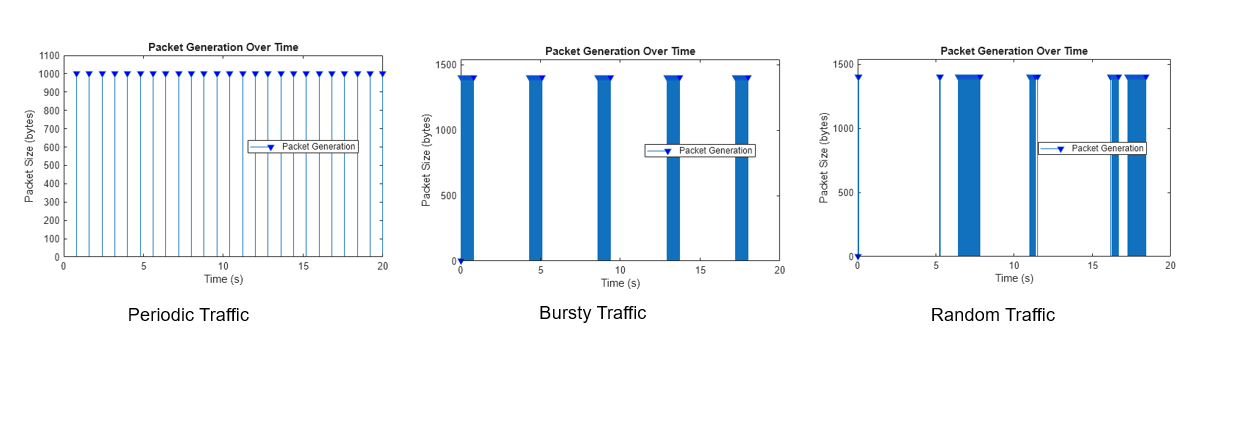

Other supported application traffic models 

- FTP (File Transfer Protocol) – Models file-based data transfer sessions.

- Video Streaming – Simulates continuous media flow with variable bit rates.

- Voice over IP (VoIP) – Models real-time voice communication traffic.

Use networkTrafficOnOff() function to configure application layer traffic. 

Write configuration in a variable named "traffic". 

Type "doc networkTrafficOnOff" in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values as arguments 

- DataRate=64

- PacketSize=251

- OnTime=simulationTime

- OffTime=0

traffic= networkTrafficOnOff(DataRate=64,PacketSize=251,OnTime=simulationTime,OffTime=0);

Visualize the configured  traffic pattern 

plotTrafficPattern(simulationTime,traffic);

Use addTrafficSource() function to add application traffic to the nodes  

Type "doc addTrafficSource" in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values as arguments 

- centralNode

- traffic

- "DestinationNode",peripheralNode

addTrafficSource(centralNode,traffic,"DestinationNode",peripheralNode);

Use addTrafficSource() function to add application traffic to the nodes  

Type "doc addTrafficSource" in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values as arguments 

- peripheralNode

- traffic

- "DestinationNode",centralNode

addTrafficSource(peripheralNode,traffic,"DestinationNode",centralNode);

Add the Central and Peripheral nodes to the wireless network simulator.

nodes = [centralNode peripheralNode];
addNodes(networkSimulator,nodes);

Configure WLAN Signal Interference 

 Bluetooth LE Piconet with WLAN interference 

- Create Access Point (AP)

- Create Station (STA)

- Set up the WLAN network

- Add WLAN nodes to the network simulator

enableWLANInterference = false;
if enableWLANInterference
    apDeviceConfig = wlanDeviceConfig(Mode="AP",BandAndChannel=[2.4 7],TransmitPower=20,InterferenceModeling="overlapping-adjacent-channel");
    staDeviceConfig = wlanDeviceConfig(Mode="STA",BandAndChannel=[2.4 7],TransmitPower=20,InterferenceModeling="overlapping-adjacent-channel");
    wlanAPNode = wlanNode(DeviceConfig=apDeviceConfig,Name="AP",Position=[3 3 0],MACModel="full-mac",PHYModel="full-phy");
    wlanSTANode = wlanNode(DeviceConfig=staDeviceConfig,Name="STA",Position=[-3 3 0], MACModel="full-mac",PHYModel="full-phy");
    associateStations(wlanAPNode,wlanSTANode,BandAndChannel=[2.4 7],FullBufferTraffic="on");
    wlanNodes = [wlanAPNode wlanSTANode];
    addNodes(networkSimulator,wlanNodes)
    addNodes(viewerObj,wlanNodes,Type="WLAN");
end

Visualize State Transitions of Nodes 

trafficViewerObj = wirelessTrafficViewer;
addNodes(trafficViewerObj,nodes);
if enableWLANInterference
    addNodes(trafficViewerObj,wlanNodes)
end    

Capture packets for all nodes in the network and visualize them in Wireshark, similar to real-world Bluetooth network behavior.

packetCaptureObj = blePCAPWriter(Node=nodes,FileExtension="pcap");

Set the simulation time in seconds and run the simulation.

run(networkSimulator,simulationTime)
delete(packetCaptureObj);

Use kpi() function to Measure the throughput 

Use doc kpi to see details  of measuring different network KPIs 

Define a variable named "throughput"

Note : use the following values and pass as argument to kpi()

- centralNode

- peripheralNode

- "throughput"

- Layer="LL"

throughput = kpi(centralNode,peripheralNode,"throughput",Layer="LL")

Use kpi() function to Measure the packet loss ratio 

Use doc kpi to see details  of measuring different network KPIs 

Define a variable named "packetLossRatio"

Note : use the following values and pass as argument to kpi()

- centralNode

- peripheralNode

- "PLR"

- Layer="App"

packetLossRatio = kpi(centralNode,peripheralNode,"PLR",Layer="App")

*Copyright 2025-2026 The MathWorks, Inc.*